# EXERCISE B -- GUIDED STIFFNESS-METHOD TUTORIAL

Determine the reactions at nodes 1 and 4. The portal is 2 m wide and 3 m high. Its bases are pins; its upper beam-to-column connections are rigid. A horizontal uniform load of 6 kN/m acts rightward along the entire left column.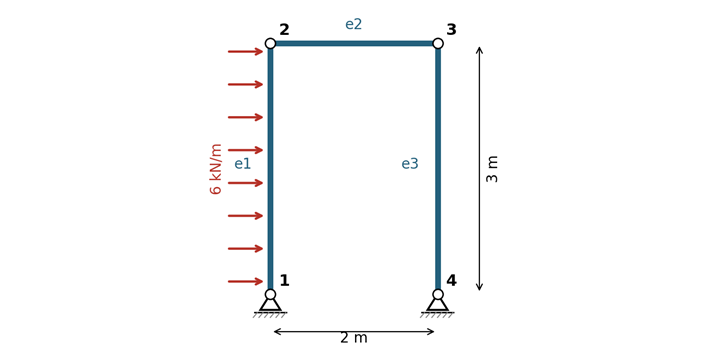

## 0. Prepare the workspace and display options

clear removes previous variables; clc clears the Command Window; close all closes earlier figures. Execute this section once at the START. showMatrices controls intermediate output, makePlots controls visualization, and deformationScale=0 requests automatic visual magnification. These switches do not change the structural solution.

clear; clc; close all;
format short g;
showMatrices = true;   % Show element matrices and assembled equations.
makePlots = true;      % Set false for numerical calculations only.
deformationScale = 0;  % Zero selects an automatic visual magnification.

## Exercise statement and modeling interpretation

Nodes follow the figure: 1 left base, 2 left top, 3 right top, 4 right base. Elements: 1 = left column (up), 2 = beam (right), 3 = right column (down). The nonsequential dofMap below preserves the figure's DOF NUMBERS.

## 1. Define material and section properties

PURPOSE: establish axial rigidity EA and bending rigidity EI. Convert 200 GPa to 200000 N/mm^2. All dimensions are entered in mm. A is cross-sectional area in mm^2; I is the second moment of area in mm^4 about the out-of-plane bending axis. Every member has the same properties, so scalar E, A and I are sufficient for these exercises.

E = 200e3;                 % N/mm^2 = 200 GPa
I = 300e6;                 % mm^4
A = 9.68e3;                % mm^2

## 2. Define node coordinates and member connectivity

PURPOSE: describe the frame as joints connected by straight members. Each row of nodes is [x y] in mm, and its row number is the node number. Each row of elements is [i j], and its row number is the element number. The i->j order defines local axes and signs; it does not change the physical frame if all associated local quantities are transformed consistently.

nodes = [0 0;             % [x y], mm
         0 3000;
         2000 3000;
         2000 0];
elements = [1 2; 2 3; 3 4];

## 3. Associate each motion with a global equation number

PURPOSE: connect physical nodal motions with positions in the solution vector. dofMap(n,:)=[index_ux index_uy index_theta] at node n. For example, d(dofMap(n,1)) returns node n's horizontal displacement. Every global index appears once. Connectivity uses NODE numbers, whereas stiffness assembly uses DOF numbers: do not confuse these two lists.

dofMap = [11 12 8;         % Node 1: ux uy theta
          1  2 3;         % Node 2
          4  5 6;         % Node 3
          9 10 7];        % Node 4

## 4. Define the support restraints

PURPOSE: distinguish a support pin from a rigid member-to-member joint. At nodes 1 and 4, constrain ONLY translations: DOFs 9,10,11,12 are zero. Base rotations 7 and 8 remain unknown, leaving eight free DOFs. Only one member meets each base, so a free base rotation enforces zero end moment without a separate element-end release formulation. At upper nodes 2 and 3, connected members share one rotation: rigid joints. Constraining base rotations would change this model to fixed supports.

fixedDofs = [9 10 11 12];  % Only translations at the two pin supports.
prescribedValues = zeros(4,1);
% IMPORTANT: DOFs 7 and 8 (base rotations) remain FREE. Do not set them to
% zero: that would create fixed supports. No internal element release is
% needed at a base connected to just one member; its free rotation enforces
% zero end moment. Upper nodes share one rotation each (rigid joints).

## 5. Define loads and their coordinate directions

PURPOSE: describe the physical member load before converting it to nodal loads. There are no concentrated point loads. The left column carries 6 kN/m to the RIGHT, equivalent to 6 N/mm. Its local x points UP and its local y points LEFT, so local qy=-6 N/mm. Local axial loading qx is zero. Stage 8 gives global horizontal end forces of +9 kN each and equivalent end moments of -4.5 kN*m at the lower end and +4.5 kN*m at the upper end. These end moments are necessary even though the actual base is a pin: the pin's zero physical end moment is recovered after solving the frame.

Fpoint = zeros(12,1);      % No concentrated nodal loads.

% 6 kN/m = 6 N/mm acts globally to the RIGHT along element 1.
% Element 1 points UP: c = 0, s = 1; its local +y points LEFT.
% Thus [qx; qy] = [c s; -s c]*[6;0] = [0;-6] N/mm.
w = 6;                    % Positive magnitude of rightward load, N/mm.
qLocal = [0 -w;
          0  0;
          0  0];
fprintf('EXERCISE B: reactions at pin supports 1 and 4\n');

EXERCISE B: reactions at pin supports 1 and 4


fprintf('Global signs: right/up/CCW positive. Internal units: N, mm, rad.\n');

Global signs: right/up/CCW positive. Internal units: N, mm, rad.


## 6. Determine element lengths, orientations and global DOF lists

PURPOSE: turn geometry into element information. For a member i->j: dx=xj-xi; dy=yj-yi; L=sqrt(dx^2+dy^2); c=dx/L; s=dy/L. c and s are direction cosines. Local x points from i to j; local y is 90 degrees counterclockwise from local x. edofs gives the six GLOBAL indices of this element in endpoint order. elementData stores one record per member, with named fields.

nNode = size(nodes,1);
nElem = size(elements,1);
nDof = 3*nNode;
assert(isequal(sort(dofMap(:)), (1:nDof).'), 'Check DOF numbering.');
elementData = struct([]);
for e = 1:nElem
    ij = elements(e,:);
    delta = nodes(ij(2),:) - nodes(ij(1),:);
    L = hypot(delta(1),delta(2));
    assert(L > 0,'An element must have nonzero length.');
    c = delta(1)/L;
    s = delta(2)/L;
    edofs = [dofMap(ij(1),:) dofMap(ij(2),:)];
    elementData(e).L = L;
    elementData(e).c = c;
    elementData(e).s = s;
    elementData(e).dofs = edofs;
    fprintf('\nElement %d: node %d -> %d, L = %.0f mm, c = %.1f, s = %.1f\n', ...
        e,ij(1),ij(2),L,c,s);
    fprintf('Element DOFs: '); fprintf('%d ',edofs); fprintf('\n');
end


Element 1: node 1 -> 2, L = 3000 mm, c = 0.0, s = 1.0


Element DOFs: 11 12 8 1 2 3 



Element 2: node 2 -> 3, L = 2000 mm, c = 1.0, s = 0.0


Element DOFs: 1 2 3 4 5 6 



Element 3: node 3 -> 4, L = 3000 mm, c = 0.0, s = -1.0


Element DOFs: 4 5 6 9 10 7 


% CHECK: rightward horizontal (c,s)=(1,0); upward vertical (0,1);
% downward vertical (0,-1). Reversing element order reverses its local axes.

## 7. Calculate the local stiffness and transform it to global axes

PURPOSE: combine axial and bending behavior in a common coordinate system. The included frameElement function gives the full 6-by-6 matrix. Its axial terms contain EA/L. Its bending terms contain 12EI/L^3, 6EI/L^2, 4EI/L and 2EI/L. A frame transmits bending moments as well as axial forces; a truss model would omit the bending behavior.

ELEMENT RELATION without member loading: qLocalEnd=kLocal*dLocal. dLocal=T*dGlobal; qGlobalEnd=T'*qLocalEnd. Consequently kGlobal=T'*kLocal*T. For each node [u;v]=[c s;-s c]*[ux;uy]; the z rotation is unchanged. Transforming forces with T' preserves virtual work in the two systems. MATLAB .' is transpose without complex conjugation.

for e = 1:nElem
    data = elementData(e);
    [kLocal,T] = frameElement(E,A,I,data.L,data.c,data.s);
    kGlobal = T.'*kLocal*T;
    elementData(e).kLocal = kLocal;
    elementData(e).T = T;
    elementData(e).kGlobal = kGlobal;
    if showMatrices
        fprintf('\nELEMENT %d STIFFNESS AND TRANSFORMATION\n',e);
        disp('Local stiffness kLocal:'); disp(kLocal);
        disp('Transformation T:'); disp(T);
        disp('Global stiffness T''*kLocal*T:'); disp(kGlobal);
    end
end


ELEMENT 1 STIFFNESS AND TRANSFORMATION


Local stiffness kLocal:
   6.4533e+05            0            0  -6.4533e+05            0            0
            0        26667        4e+07            0       -26667        4e+07
            0        4e+07        8e+10            0       -4e+07        4e+10
  -6.4533e+05            0            0   6.4533e+05            0            0
            0       -26667       -4e+07            0        26667       -4e+07
            0        4e+07        4e+10            0       -4e+07        8e+10



Transformation T:
     0     1     0     0     0     0
    -1     0     0     0     0     0
     0     0     1     0     0     0
     0     0     0     0     1     0
     0     0     0    -1     0     0
     0     0     0     0     0     1



Global stiffness T'*kLocal*T:
        26667            0       -4e+07       -26667            0       -4e+07
            0   6.4533e+05            0            0  -6.4533e+05            0
       -4e+07            0        8e+10        4e+07            0        4e+10
       -26667            0        4e+07        26667            0        4e+07
            0  -6.4533e+05            0            0   6.4533e+05            0
       -4e+07            0        4e+10        4e+07            0        8e+10




ELEMENT 2 STIFFNESS AND TRANSFORMATION


Local stiffness kLocal:
     9.68e+05            0            0    -9.68e+05            0            0
            0        90000        9e+07            0       -90000        9e+07
            0        9e+07      1.2e+11            0       -9e+07        6e+10
    -9.68e+05            0            0     9.68e+05            0            0
            0       -90000       -9e+07            0        90000       -9e+07
            0        9e+07        6e+10            0       -9e+07      1.2e+11



Transformation T:
     1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1



Global stiffness T'*kLocal*T:
     9.68e+05            0            0    -9.68e+05            0            0
            0        90000        9e+07            0       -90000        9e+07
            0        9e+07      1.2e+11            0       -9e+07        6e+10
    -9.68e+05            0            0     9.68e+05            0            0
            0       -90000       -9e+07            0        90000       -9e+07
            0        9e+07        6e+10            0       -9e+07      1.2e+11




ELEMENT 3 STIFFNESS AND TRANSFORMATION


Local stiffness kLocal:
   6.4533e+05            0            0  -6.4533e+05            0            0
            0        26667        4e+07            0       -26667        4e+07
            0        4e+07        8e+10            0       -4e+07        4e+10
  -6.4533e+05            0            0   6.4533e+05            0            0
            0       -26667       -4e+07            0        26667       -4e+07
            0        4e+07        4e+10            0       -4e+07        8e+10



Transformation T:
     0    -1     0     0     0     0
     1     0     0     0     0     0
     0     0     1     0     0     0
     0     0     0     0    -1     0
     0     0     0     1     0     0
     0     0     0     0     0     1



Global stiffness T'*kLocal*T:
        26667            0        4e+07       -26667            0        4e+07
            0   6.4533e+05            0            0  -6.4533e+05            0
        4e+07            0        8e+10       -4e+07            0        4e+10
       -26667            0       -4e+07        26667            0       -4e+07
            0  -6.4533e+05            0            0   6.4533e+05            0
        4e+07            0        4e+10       -4e+07            0        8e+10



% CHECK: both stiffness matrices are symmetric. Entries have mixed units
% because force/moment rows and translation/rotation columns coexist.

## 8. Convert distributed member loading into equivalent nodal actions

PURPOSE: represent continuous loading in the nodal equilibrium equations. For uniform local loads qx and qy (N/mm), the CONSISTENT load vector is: [qx*L/2; qy*L/2; qy*L^2/12; qx*L/2; qy*L/2; -qy*L^2/12]. It follows from integrating the load against the element shape functions. Two transverse forces alone can balance the resultant but do not preserve virtual work for arbitrary nodal rotations: include the end moments too. These equivalent actions are not the unknown support reactions. The global equivalent vector is fGlobal=T'*fLocal.

for e = 1:nElem
    L = elementData(e).L;
    T = elementData(e).T;
    qx = qLocal(e,1);
    qy = qLocal(e,2);
    fLocal = [qx*L/2; qy*L/2; qy*L^2/12;
              qx*L/2; qy*L/2; -qy*L^2/12];
    fGlobal = T.'*fLocal;
    elementData(e).fLocal = fLocal;
    elementData(e).fGlobal = fGlobal;
    if showMatrices
        fprintf('\nELEMENT %d EQUIVALENT NODAL LOADS\n',e);
        disp('Local order [Ni Vi Mi Nj Vj Mj]''; N and N*mm:'); disp(fLocal);
        disp('Same vector in global axes:'); disp(fGlobal);
    end
end


ELEMENT 1 EQUIVALENT NODAL LOADS


Local order [Ni Vi Mi Nj Vj Mj]'; N and N*mm:
           0
       -9000
    -4500000
           0
       -9000
     4500000



Same vector in global axes:
        9000
           0
    -4500000
        9000
           0
     4500000




ELEMENT 2 EQUIVALENT NODAL LOADS


Local order [Ni Vi Mi Nj Vj Mj]'; N and N*mm:
     0
     0
     0
     0
     0
     0



Same vector in global axes:
     0
     0
     0
     0
     0
     0




ELEMENT 3 EQUIVALENT NODAL LOADS


Local order [Ni Vi Mi Nj Vj Mj]'; N and N*mm:
     0
     0
     0
     0
     0
     0



Same vector in global axes:
     0
     0
     0
     0
     0
     0



## 9. Assemble the global stiffness matrix and load vector

PURPOSE: combine member equations while enforcing joint compatibility. K begins as an nDof-by-nDof zero matrix; F begins with concentrated loads. K(edofs,edofs) selects the element's 6-by-6 contribution within the frame. ADD each transformed matrix and load vector; do not overwrite existing contributions at a shared joint. Shared nodal translations and rotations enforce compatibility between connected members and their rigid joint. The full K has rigid-body modes before support restraints are applied. We therefore solve the reduced restrained system, not K*d=F directly.

K = zeros(nDof);
F = Fpoint;
for e = 1:nElem
    edofs = elementData(e).dofs;
    K(edofs,edofs) = K(edofs,edofs) + elementData(e).kGlobal;
    F(edofs) = F(edofs) + elementData(e).fGlobal;
end
if showMatrices
    disp('ASSEMBLED K:'); disp(K);
    disp('ASSEMBLED F:'); disp(F);
end

ASSEMBLED K:
   9.9467e+05            0        4e+07    -9.68e+05            0            0            0        4e+07            0            0       -26667            0
            0   7.3533e+05        9e+07            0       -90000        9e+07            0            0            0            0            0  -6.4533e+05
        4e+07        9e+07        2e+11            0       -9e+07        6e+10            0        4e+10            0            0       -4e+07            0
    -9.68e+05            0            0   9.9467e+05            0        4e+07        4e+07            0       -26667            0            0            0
            0       -90000       -9e+07            0   7.3533e+05       -9e+07            0            0            0  -6.4533e+05            0            0
            0        9e+07        6e+10        4e+07       -9e+07        2e+11        4e+10            0       -4e+07            0            0            0
            0            0            0      

ASSEMBLED F:
        9000
           0
     4500000
           0
           0
           0
           0
    -4500000
           0
           0
        9000
           0



## 10. Partition the equations using the support conditions

PURPOSE: solve only for motions that are genuinely unknown. Let f mean free and c mean constrained: Kff*df+Kfc*dc=Ff, so Kff*df=Ff-Kfc*dc. setdiff finds all DOFs not listed in fixedDofs. Initialize the complete d, insert prescribed support motions dc, and extract Kff and rhs in freeDofs order. Here dc=0; retaining Kfc*dc also supports imposed nonzero motions.

% Partition: Kff*df + Kfc*dc = Ff, where dc contains known displacements.
% Backslash solves the system directly; an explicit inverse is unnecessary.
freeDofs = setdiff(1:nDof,fixedDofs);
d = zeros(nDof,1);
d(fixedDofs) = prescribedValues;
Kff = K(freeDofs,freeDofs);
rhs = F(freeDofs) - K(freeDofs,fixedDofs)*d(fixedDofs);

## 11. Check stability and solve for the free displacements

PURPOSE: obtain the unique elastic solution of the restrained frame. K must be symmetric. Kff should be positive definite for this stable model; chol returns a nonzero flag if that property is absent. MATLAB backslash solves the linear system without explicitly forming inv(Kff). Insert the solved free motions into their original positions in d.

assert(norm(K-K.','fro') <= 1e-12*norm(K,'fro'), 'K must be symmetric.');
[~,cholFlag] = chol(Kff);
assert(cholFlag == 0, 'The restrained frame is unstable or incorrectly assembled.');
d(freeDofs) = Kff \ rhs;

if showMatrices
    fprintf('\nASSEMBLED SYSTEM\n');
    disp('Full K (mixed force/moment and translation/rotation units):'); disp(K);
    disp('Equivalent global load vector F:'); disp(F);
    disp('Free DOFs, in reduced-system order:'); disp(freeDofs);
    disp('Reduced stiffness Kff:'); disp(Kff);
    disp('Reduced right-hand side:'); disp(rhs);
end


ASSEMBLED SYSTEM


Full K (mixed force/moment and translation/rotation units):
   9.9467e+05            0        4e+07    -9.68e+05            0            0            0        4e+07            0            0       -26667            0
            0   7.3533e+05        9e+07            0       -90000        9e+07            0            0            0            0            0  -6.4533e+05
        4e+07        9e+07        2e+11            0       -9e+07        6e+10            0        4e+10            0            0       -4e+07            0
    -9.68e+05            0            0   9.9467e+05            0        4e+07        4e+07            0       -26667            0            0            0
            0       -90000       -9e+07            0   7.3533e+05       -9e+07            0            0            0  -6.4533e+05            0            0
            0        9e+07        6e+10        4e+07       -9e+07        2e+11        4e+10            0       -4e+07            0            0            

Equivalent global load vector F:
        9000
           0
     4500000
           0
           0
           0
           0
    -4500000
           0
           0
        9000
           0



Free DOFs, in reduced-system order:
     1     2     3     4     5     6     7     8



Reduced stiffness Kff:
   9.9467e+05            0        4e+07    -9.68e+05            0            0            0        4e+07
            0   7.3533e+05        9e+07            0       -90000        9e+07            0            0
        4e+07        9e+07        2e+11            0       -9e+07        6e+10            0        4e+10
    -9.68e+05            0            0   9.9467e+05            0        4e+07        4e+07            0
            0       -90000       -9e+07            0   7.3533e+05       -9e+07            0            0
            0        9e+07        6e+10        4e+07       -9e+07        2e+11        4e+10            0
            0            0            0        4e+07            0        4e+10        8e+10            0
        4e+07            0        4e+10            0            0            0            0        8e+10



Reduced right-hand side:
        9000
           0
     4500000
           0
           0
           0
           0
    -4500000



## 12. Recover reactions and organize the nodal displacements

PURPOSE: substitute the solved motions into the FULL unreduced equations. R=K*d-F gives support reactions at constrained DOFs and numerical zeros at free DOFs. F must include equivalent member loads as well as point loads. d(dofMap.') gathers entries in node order; reshape and transpose produce one row per node: [ux uy theta]. The table reports mm, mm and radians.

% R = K*d-F includes distributed loads through their assembled equivalent
% nodal vector. Free-DOF entries should be numerical roundoff only.
R = K*d - F;
nodalD = reshape(d(dofMap.'),3,nNode).';
nodalR = reshape(R(dofMap.'),3,nNode).';
displacementTable = table((1:nNode).',dofMap(:,1),dofMap(:,2),dofMap(:,3), ...
    nodalD(:,1),nodalD(:,2),nodalD(:,3), ...
    'VariableNames',{'Node','DOF_ux','DOF_uy','DOF_theta','ux_mm','uy_mm','theta_rad'});
fprintf('\nNODAL DISPLACEMENTS (positive right/up/CCW)\n');


NODAL DISPLACEMENTS (positive right/up/CCW)


disp(displacementTable);

    Node    DOF_ux    DOF_uy    DOF_theta    ux_mm       uy_mm       theta_rad 
    ____    ______    ______    _________    ______    _________    ___________

     1        11        12          8             0            0    -0.00058919
     2         1         2          3        1.1341     0.020919    -6.8229e-05
     3         4         5          6        1.1289    -0.020919    -0.00012361
     4         9        10          7             0            0    -0.00050264



## 13. Display the support reactions in kN and kN*m

PURPOSE: extract support-node actions and convert from internal units. Divide N by 1000 and N*mm by 1000000. Reactions act FROM the support ON the frame; positive means right/up/CCW. A downward vertical pin reaction means that the support must hold the frame down: uplift demand on anchorage. Pin moment entries are free-DOF residuals and should be numerical zero.

supportNodes = find(any(ismember(dofMap,fixedDofs),2));
reactionTable = table(supportNodes,nodalR(supportNodes,1)/1e3, ...
    nodalR(supportNodes,2)/1e3,nodalR(supportNodes,3)/1e6, ...
    'VariableNames',{'Node','Rx_kN','Ry_kN','Mz_kNm'});
fprintf('SUPPORT REACTIONS (positive right/up/CCW)\n');

SUPPORT REACTIONS (positive right/up/CCW)


disp(reactionTable);

    Node     Rx_kN     Ry_kN      Mz_kNm   
    ____    _______    _____    ___________

     1      -12.946    -13.5              0
     4      -5.0538     13.5    -7.4506e-15



## 14. Recover axial force, shear force and moment at each member end

PURPOSE: obtain the actions applied TO each member at its two ends. Extract its six global displacements; transform them by dLocal=T*dGlobal. Then qEnd=kLocal*dLocal-fLocal. Subtracting the consistent load vector accounts for load-induced fixed-end actions. kLocal*dLocal alone is wrong for a member with distributed loading. Order is [Ni Vi Mi Nj Vj Mj]; both end moments are positive CCW. These endpoint actions use a different convention from opposite-face signs often chosen for internal force diagrams; do not equate their signs directly.

endForcesLocal = zeros(nElem,6);
for e = 1:nElem
    data = elementData(e);
    dLocal = data.T*d(data.dofs);
    % Subtract the consistent load vector. kLocal*dLocal alone gives the
    % wrong end actions when the member carries distributed loading.
    qEnd = data.kLocal*dLocal - data.fLocal;
    elementData(e).dLocal = dLocal;
    endForcesLocal(e,:) = qEnd.';
end
endForceTable = table((1:nElem).',endForcesLocal(:,1)/1e3, ...
    endForcesLocal(:,2)/1e3,endForcesLocal(:,3)/1e6, ...
    endForcesLocal(:,4)/1e3,endForcesLocal(:,5)/1e3,endForcesLocal(:,6)/1e6, ...
    'VariableNames',{'Element','Ni_kN','Vi_kN','Mi_kNm','Nj_kN','Vj_kN','Mj_kNm'});
fprintf('LOCAL END ACTIONS applied TO each member, in its local axes\n');

LOCAL END ACTIONS applied TO each member, in its local axes


fprintf('Order: [Ni Vi Mi Nj Vj Mj]; moments positive CCW at both ends.\n');

Order: [Ni Vi Mi Nj Vj Mj]; moments positive CCW at both ends.


fprintf('These are end actions, not a bending-diagram sign convention.\n');

These are end actions, not a bending-diagram sign convention.


disp(endForceTable);

    Element    Ni_kN     Vi_kN       Mi_kNm       Nj_kN      Vj_kN       Mj_kNm   
    _______    ______    ______    __________    _______    _______    ___________

       1        -13.5    12.946    1.8626e-15       13.5     5.0538         11.839
       2       5.0538     -13.5       -11.839    -5.0538       13.5        -15.161
       3         13.5    5.0538        15.161      -13.5    -5.0538    -7.4506e-15



## 15. Check free-DOF equilibrium and whole-frame static balance

PURPOSE: verify sum(Fx)=0, sum(Fy)=0 and sum(M_origin)=0. A force at [x,y] contributes moment x*Fy-y*Fx. Here a uniform load is represented by its physical resultant at the member centroid, independently of the equivalent nodal loading used to solve the system. Numerical roundoff is normal; assert stops if a tolerance is exceeded.

% Sum the physical forces/moments (distributed loads at their centroids).
% This independently checks the assembled consistent-load vector.
pointNodal = reshape(Fpoint(dofMap.'),3,nNode).';
balance = [sum(pointNodal(:,1)+nodalR(:,1));
           sum(pointNodal(:,2)+nodalR(:,2));
           sum(pointNodal(:,3)+nodalR(:,3) ...
             + nodes(:,1).*(pointNodal(:,2)+nodalR(:,2)) ...
             - nodes(:,2).*(pointNodal(:,1)+nodalR(:,1)))];
for e = 1:nElem
    data = elementData(e);
    xy = mean(nodes(elements(e,:),:),1);
    qGlobal = [data.c -data.s; data.s data.c]*qLocal(e,:).';
    resultant = qGlobal*data.L;
    balance = balance + [resultant;
        xy(1)*resultant(2)-xy(2)*resultant(1)];
end
forceScale = max(1,norm(F,inf));
lengthScale = max([elementData.L]);
assert(norm(R(freeDofs),inf) < 1e-9*forceScale, 'Free-DOF equilibrium failed.');
assert(norm(balance(1:2),inf) < 1e-8*forceScale, 'Force equilibrium failed.');
assert(abs(balance(3)) < 1e-8*forceScale*lengthScale, 'Moment equilibrium failed.');
fprintf('Equilibrium residual: Fx = %.3e N, Fy = %.3e N, M = %.3e N*mm\n',balance);

Equilibrium residual: Fx = -2.437e-10 N, Fy = 0.000e+00 N, M = 7.153e-07 N*mm


## 16. Compare with an independent analytical solution

PURPOSE: verify reactions using compatibility instead of stiffness assembly. There is one external redundancy. Release the horizontal restraint at node 4, keeping its vertical restraint, and call the released reaction X. The real load produces a horizontal displacement delta0 at this point; a unit horizontal load there defines flexibility fxx. Restoring the support requires delta0+fxx*X=0, hence X=-delta0/fxx. fxx includes bending in both columns and the beam, plus beam axial deformation. Column axial terms vanish for this unit-load case. Statics gives the other reactions after X is known. EXPECTED, positive right/up: Rx1=-12.94620144 kN; Ry1=-13.5 kN; Rx4=-5.05379856 kN; Ry4=+13.5 kN; both support moments zero.

% Release only the horizontal restraint at node 4. The resulting primary
% frame has a left pin and a right vertical roller, and is determinate.
% Choose X = horizontal reaction at node 4, positive right.
%
% Unit-load integration gives horizontal displacement delta0 from the UDL:
% delta0 = w/(E*I)*(5*H^4/24 + H^3*B/4).
% The flexibility at this released DOF, including beam axial deformation:
% flexibility = (2*H^3/3 + H^2*B)/(E*I) + B/(E*A).
% Compatibility requires delta0 + flexibility*X = 0.
% Both columns contribute bending flexibility; the beam contributes bending
% and axial flexibility. Column axial terms vanish for this unit load.
B = 2000; H = 3000;
delta0 = w*(5*H^4/24 + H^3*B/4)/(E*I);
flexibility = (2*H^3/3 + H^2*B)/(E*I) + B/(E*A);
X = -delta0/flexibility;
Rx1 = -w*H-X;
Rx4 = X;
Ry4 = w*H^2/(2*B);
Ry1 = -Ry4;
rAnalytical = [Rx1; Ry1; Rx4; Ry4];
rComputed = R([dofMap(1,1:2) dofMap(4,1:2)]);
assert(all(abs(rComputed-rAnalytical) < 1e-8*max(abs(rAnalytical),1)), ...
    'Independent force-method check failed.');
% Pins cannot transmit moments. Local end i of member 1 is node 1;
% local end j of member 3 is node 4.
assert(abs(endForcesLocal(1,3)) < 1e-5, 'Left pin has a nonzero end moment.');
assert(abs(endForcesLocal(3,6)) < 1e-5, 'Right pin has a nonzero end moment.');
fprintf('\nREQUESTED ANSWER -- PIN SUPPORT REACTIONS\n');


REQUESTED ANSWER -- PIN SUPPORT REACTIONS


fprintf('Node 1: Rx = %+.8f kN, Ry = %+.8f kN, M = 0 kN*m\n',Rx1/1e3,Ry1/1e3);

Node 1: Rx = -12.94620144 kN, Ry = -13.50000000 kN, M = 0 kN*m


fprintf('Node 4: Rx = %+.8f kN, Ry = %+.8f kN, M = 0 kN*m\n',Rx4/1e3,Ry4/1e3);

Node 4: Rx = -5.05379856 kN, Ry = +13.50000000 kN, M = 0 kN*m


fprintf('Negative Rx = left; negative Ry = down. A negative Ry is uplift demand.\n');

Negative Rx = left; negative Ry = down. A negative Ry is uplift demand.


fprintf('Force-method and stiffness-method reactions agree.\n');

Force-method and stiffness-method reactions agree.


## 17. Relate the solution to the magnified deformed shape

PURPOSE: see how nodal motion and member curvature combine. The model panel shows nodes, members, supports and loads in metres. The deformed panel magnifies small elastic motions; read its stated scale. Do not infer actual deflections from that magnified drawing. The included function uses Hermite bending shape functions, linear axial interpolation and uniform-load particular solutions. Joining displaced nodes with straight lines would hide curvature. The plot visualizes a linear solution, not a nonlinear analysis of the enlarged deformed geometry.

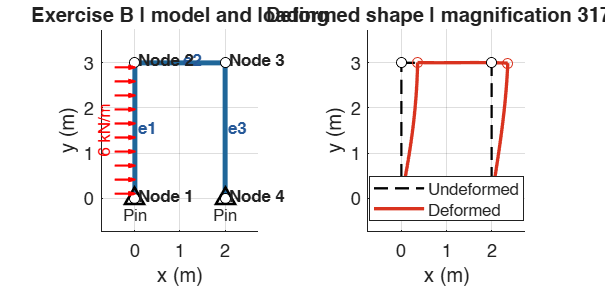

if makePlots
    plotFrame(nodes,elements,dofMap,d,elementData,qLocal,E,A,I, ...
        supportNodes,fixedDofs,deformationScale,'Exercise B');
    subplot(1,2,1); hold on;
    yy = linspace(0.1,2.9,10);
    quiver(-0.45*ones(size(yy)),yy,0.45*ones(size(yy)),zeros(size(yy)), ...
        0,'r','LineWidth',1.3,'MaxHeadSize',0.4);
    text(-0.48,1.5,'6 kN/m','Color','r','Rotation',90, ...
        'HorizontalAlignment','center','VerticalAlignment','bottom');
end

% Useful workspace variables: K, F, Kff, d, R, elementData,
% displacementTable, reactionTable, endForceTable, rAnalytical.

## 18. Classroom investigations and interpretation

Run the baseline model before experimenting. If loads or geometry change, update the analytical-check inputs consistently or skip that section. Suggested investigations: - Double E only: all displacements halve; reactions remain unchanged here. - Increase A only: identify the influence of axial flexibility. - Explain why full K has rigid-body modes but restrained Kff does not. - Reverse a member's node order and transform its local loads consistently; the global physical solution must remain unchanged. Exercise-specific discussion: - Why is the left vertical reaction downward? - Why are base rotations unknown when base moments are zero? - Why must a uniform load generate equivalent nodal moments?

Execute numbered sections in order, or run the whole file. The supporting local functions below are not additional exercise stages.

## LOCAL FUNCTIONS -- supporting routines

function [k,T] = frameElement(E,A,I,L,c,s)
% 2-node, 6-DOF Euler-Bernoulli plane-frame stiffness in LOCAL axes.
% Axial stiffness: EA/L. Bending stiffness: EI times powers of 1/L.
% Axial entries occupy rows/columns 1 and 4; bending uses 2,3,5,6.
% Off-diagonal terms couple end translations and rotations.
% T applies a coordinate-rotation block to each endpoint; the
% out-of-plane nodal rotation retains the same CCW sign.
    a = E*A/L;
    b = 12*E*I/L^3;
    g = 6*E*I/L^2;
    h = 4*E*I/L;
    j = 2*E*I/L;
    k = [ a  0  0 -a  0  0;
          0  b  g  0 -b  g;
          0  g  h  0 -g  j;
         -a  0  0  a  0  0;
          0 -b -g  0  b -g;
          0  g  j  0 -g  h];
    T = [ c  s  0  0  0  0;
         -s  c  0  0  0  0;
          0  0  1  0  0  0;
          0  0  0  c  s  0;
          0  0  0 -s  c  0;
          0  0  0  0  0  1];
end

function plotFrame(nodes,elements,dofMap,d,data,qLocal,E,A,I, ...
    supportNodes,fixedDofs,scale,caption)
% Bending uses Hermite interpolation plus the exact UDL particular solution.
% A straight line between displaced nodes would hide member curvature.
% The particular terms vanish at the ends (and their bending slopes vanish).
    nElem = size(elements,1);
    shape = cell(nElem,1);
    maxDisplacement = 0;
    for e = 1:nElem
        L = data(e).L;
        x = linspace(0,L,81);
        z = x/L;
        dl = data(e).dLocal;
        u = (1-z)*dl(1)+z*dl(4) + qLocal(e,1)*x.*(L-x)/(2*E*A);
        N1 = 1-3*z.^2+2*z.^3;
        N2 = L*(z-2*z.^2+z.^3);
        N3 = 3*z.^2-2*z.^3;
        N4 = L*(-z.^2+z.^3);
        v = N1*dl(2)+N2*dl(3)+N3*dl(5)+N4*dl(6) ...
            + qLocal(e,2)*x.^2.*(L-x).^2/(24*E*I);
        displacement = [data(e).c -data(e).s; data(e).s data(e).c]*[u;v];
        origin = nodes(elements(e,1),:).';
        xy = repmat(origin,1,numel(x)) + [data(e).c;data(e).s]*x;
        shape{e} = struct('xy',xy,'displacement',displacement);
        maxDisplacement = max(maxDisplacement,max(sqrt(sum(displacement.^2,1))));
    end
    span = max(max(nodes,[],1)-min(nodes,[],1));
    if scale <= 0
        scale = 0.12*span/max(maxDisplacement,eps);
    end
    figure('Color','w','Name',caption,'Position',[100 100 1100 520]);
    for panel = 1:2
        subplot(1,2,panel); hold on; grid on; axis equal;
        for e = 1:nElem
            xy = shape{e}.xy/1000;    % Display geometry in metres.
            h0 = plot(xy(1,:),xy(2,:),'k--','LineWidth',1.4);
            if panel == 1
                plot(xy(1,:),xy(2,:),'Color',[0.12 0.4 0.6],'LineWidth',3);
                midpoint = mean(xy,2);
                text(midpoint(1)+0.06,midpoint(2)+0.08,sprintf('e%d',e), ...
                    'Color',[0.15 0.35 0.6],'FontWeight','bold');
            else
                xyd = (shape{e}.xy+scale*shape{e}.displacement)/1000;
                h1 = plot(xyd(1,:),xyd(2,:),'-','Color',[0.85 0.2 0.12],'LineWidth',2);
            end
        end
        plot(nodes(:,1)/1000,nodes(:,2)/1000,'ko','MarkerFaceColor','w');
        for n = supportNodes.'
            if ismember(dofMap(n,3),fixedDofs)
                marker = 's'; label = 'Fixed';
            else
                marker = '^'; label = 'Pin';
            end
            plot(nodes(n,1)/1000,nodes(n,2)/1000,marker, ...
                'Color','k','MarkerSize',10,'LineWidth',1.5);
            text(nodes(n,1)/1000,nodes(n,2)/1000-0.13,label, ...
                'HorizontalAlignment','center','VerticalAlignment','top');
        end
        if panel == 1
            for n = 1:size(nodes,1)
                text(nodes(n,1)/1000+0.08,nodes(n,2)/1000+0.08, ...
                    sprintf('Node %d',n),'FontWeight','bold');
            end
            title([caption ' | model and loading']);
        else
            dd = reshape(d(dofMap.'),3,size(nodes,1)).';
            plot((nodes(:,1)+scale*dd(:,1))/1000, ...
                (nodes(:,2)+scale*dd(:,2))/1000,'o','Color',[0.85 0.2 0.12]);
            title(sprintf('Deformed shape | magnification %.1f',scale));
            legend([h0 h1],{'Undeformed','Deformed'},'Location','best');
        end
        xlabel('x (m)'); ylabel('y (m)');
        pad = 0.25*span/1000;
        xlim([min(nodes(:,1))/1000-pad,max(nodes(:,1))/1000+pad]);
        ylim([min(nodes(:,2))/1000-pad,max(nodes(:,2))/1000+pad]);
        set(gca,'FontSize',11);
    end
end